clear all
close all
addpath ./Functions;
N=10000;  
Student = 'Sharon Patrone';
% Used by the course-provided functions to generate the personalized dataset.
% The original matriculation number has been removed for privacy.
Matriculation = 'YOUR_ID'; 
[Measurements] = IdentifyThis(N, Student, Matriculation);
u=Measurements.u;
y=Measurements.y;

## **Exercise 1: Estimation **

In this exercise you are asked to **estimate** an unknown linear model and **display it**.

- **Understand the model structure**: The provided signals refer to either a ARX or an AR model. You should get the structure straight away from the measurements. Show why you chose one of them. 

- **Define the required estimation algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to implement the recursive version of the estimation algorithm that does not involve the matrix inversion lemma and does not involve the forgetting factor.

- **Estimate the model order: **describe the criteria you plan to use and add brief description of the matlab function you implemented to do that.

- **Validate the model: **describe the criteria with hypothesis testing you plan to use to get model validation and add a description of the matlab functions you implemented to do that. 

## 1.Model Structure

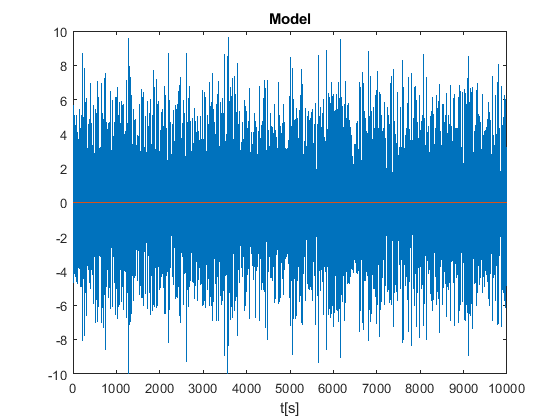

%Model
plot(Measurements.y);
hold on;
plot(Measurements.u);
xlabel('t[s]');
title('Model');

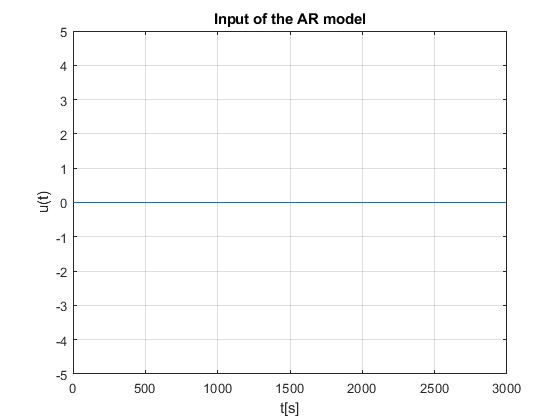

%Input
figure();
plot(u(1:3000));
grid on;
ylabel('u(t)');
ylim([-5 5]);
xlabel('t[s]');
title('Input of the AR model');

Since the input signal is identically zero, no input-dependent dynamics can be identified and, among the two candidate structures AR and ARX, an AR model is appropriate.

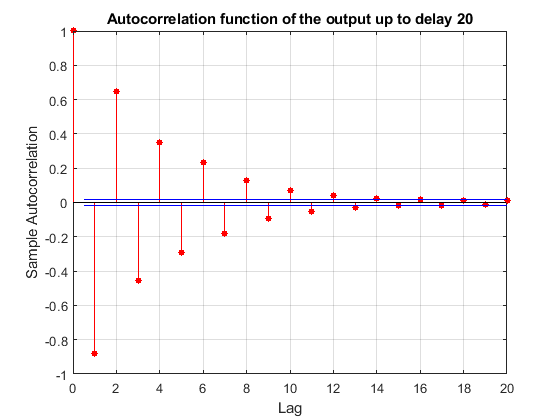

%Autocorrelation function:
figure()
autocorr(y,NumLags=20)
title ('Autocorrelation function of the output up to delay 20')

The decaying autocorrelation of the output is also consistent with an autoregressive process.

## 2.ESTIMATION ALGORITHM

An AutoRegressive (AR) model of order $n$ can be described by the following equation:


$$y(t) + a_1 y(t-1) + \dots + a_ny(t-n)  =  e(t)$$


where $y(t)$ is the output and $e(t)$ is the error term, a zero-mean white process with variance $\sigma_{\epsilon }^2$.

So we need to estimate $p=n$ parameter, which is the complexity of the model.

Let's write the model in the linear regression form, as it is linear in the parameters $a_1,a_2,...,a_n$:	


$$y(t)=\varphi^T(t) \theta + e(t)
$$


where $\varphi(t)=[-y(t-1) \cdots-y(t-n) ]^{T}$ is the vector of regressors and $\theta=\left[a_{1} \ a_{2} \cdots a_{n} \right]^{T}$ is the parameter vector to be estimated.

Our aim is to find an estimate $\hat\theta$ that minimizes the loss function: $J(\hat\theta)=\frac{1}{N}\sum_{t=1}^N \epsilon^2(t)=\frac{1}{N}\epsilon^T\epsilon=\frac{1}{N}\|\epsilon\|^2
$

where $\varepsilon=[\varepsilon(1) \ \varepsilon(2) \ldots \ \varepsilon(N)]^{T}$ is the vector of residuals. 

The linear regression can be written in the matrix form $Y=H \ \hat{\theta}+\epsilon$, where: $Y=\left[\begin{array}{lll}
y(1) y(2) & \ldots & y(N)
\end{array}\right]^{T}, \quad H=\left[\begin{array}{c}
\varphi^{T}(1) \\
\varphi^{T}(2) \\
\vdots \\
\varphi^{T}(N)
\end{array}\right] = \left[-H_y  \right]$   

$H$ is called Hankel matrix and in the case of the AR model it is:   $H_{y}(n)=\left[\begin{array}{cccc}
y(0) & y(-1) & \cdots & y(1-n) \\
y(1) & y(0) & \cdots & y(2-n) \\
\vdots & \vdots & \cdots & \vdots \\
y(N-1) & y(N-2) & \cdots & y(N-n)
\end{array}\right]$ 

In order to find our $\hat\theta$, we can use the LS estimate:  $\hat{\theta}=\left(\frac{H^{T} H}{N}\right)^{-1} \frac{H^{T} Y}{N}=\left(\frac{1}{N} \sum_{t=1}^{N} \varphi(t) \varphi^{T}(t)\right)^{-1} \frac{1}{N} \sum_{t=1}^{N} \varphi(t) y(t)$ 

Then we use the Recursive identification method, which compute $\hat\theta(t)$ by updating $\hat\theta(t-1)$ by some simple modification, and in particular the Recursive Least Square algorithm to estimate recursively $\hat\theta(t)$. We use RLSII because of the previously introduced loss function, so theta is:


$$\hat{\theta}(t)=\left( \frac{1}{T}\sum_{k=1}^{t}\varphi(k) \varphi^{T}(k)\right)^{-1}\frac{1}{T} \sum_{k=1}^{t}\varphi(k) y(k)$$


Now, defining$\left( \frac{1}{T}\sum_{k=1}^{t}\varphi(k) \varphi^{T}(k)\right)^{-1}\$= $\left(R)^{-1}\$ the second type of Recursive Least Square Algorithm can be defined as follows:

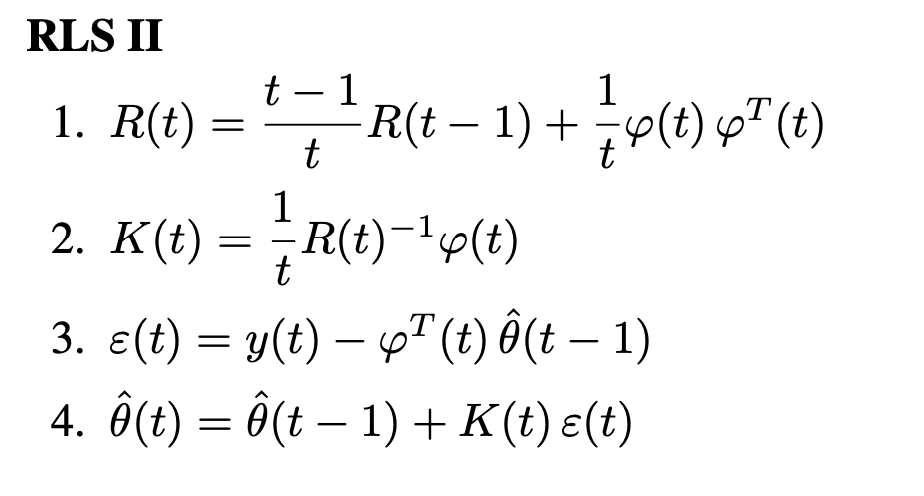

This is what is implemented in the algorithm below, assuming the system order is equal to 4, and thus the dimension of the vector representing an AR model, $p = n$.

n = 4;
Theta_LS_AR= RLSII_AR(y, n);
disp(Theta_LS_AR);

    1.6704
    1.2968
    0.6342
    0.1315



## **3. Estimate the model order: **

In order to estimate the correct order for our model, it is essential to consider two primary factors:

- Firstly, we should avoid overfitting and underfitting, as these not only increase computational load but can also lead to identifiability issues.

- Secondly, we adhere to the Parsimony Principle: when choosing between models that adequately fit our data, preference should always be given to the one with lower complexity.

To determine the order n, using the loss function is discouraged because it tends to decrease and overfit the data as n increases. Instead, we rely on different criteria such as FPE (Final Prediction Error), AIC (Akaike Information Criterion), and MDL (Minimum Description Length), which belong to the family of *criteria with complexity terms.*

### FPE (Final Prediction Error)

First method  is the ***FPE (FINAL PREDICTION ERROR)***:


$$FPE=\hat{\sigma^{2}_e}\frac{N+p}{N} = \frac{N+p}{N-p} J(\hat{\theta_N}) = J(\hat{\theta_N}) + \frac{2p}{N}J(\hat{\theta_N})$$


where p is the complexity of the model (in our case p=n for AR), and the second term is just a penalization of the cost function to avoid overfitting.

Given a model class$ M(\theta )$, we can use this criterion to estimate the best complexity p of the model, that gives the ‘best’ model class $Mp(\theta )$.  

The order giving the smallest value of the criterion function is selected.

We start with n = 1, compute the LS estimate, then the loss function, and finally we chose the order corresponding to the lower FPE value. 

L=20;
 for n=1:L
    Theta_LS=RLSII_AR(y,n);
    FPE(n)=FPE_criterion(y,Theta_LS);
end
[value,min_FPE]=min(FPE);
x = sprintf('min(FPE) is %d on the order %d.', value, min_FPE);
disp(x);

min(FPE) is 9.993517e-01 on the order 6.


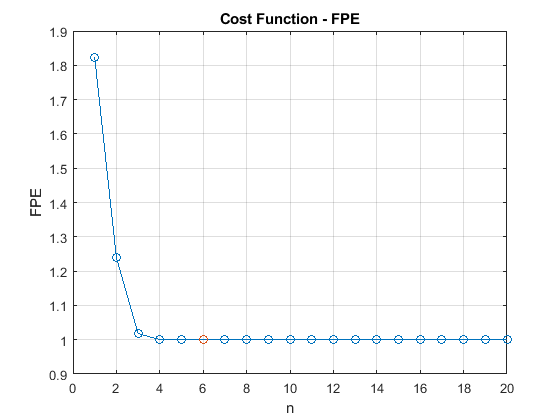

figure();
plot(FPE,'-o');
hold on;
grid on;
ylabel('FPE');
plot(min_FPE,FPE(min_FPE),'o');
xlabel('n');
title('Cost Function - FPE');

Second method is the ***MDL (MINIMUM DESCRIPTION LENGTH)***:


$$MDL=N log(J(\hat{\theta_N})) + 2p log(N)$$


Given a model class$ M(\theta )$, we can use this criterion to estimate the best complexity p of the model, that gives the ‘best’ model class $Mp(\theta )$.  

The order giving the smallest value of the criterion function is selected.

for n=1:L
    Theta_LS = RLSII_AR(y,n);
    MDL(n)=MDL_criterion(y,Theta_LS);
end
[value,min_MDL]=min(MDL);
x = sprintf('min(MDL) is %d on the order %d.', value, min_MDL);
disp(x);

min(MDL) is 6.840092e+01 on the order 4.


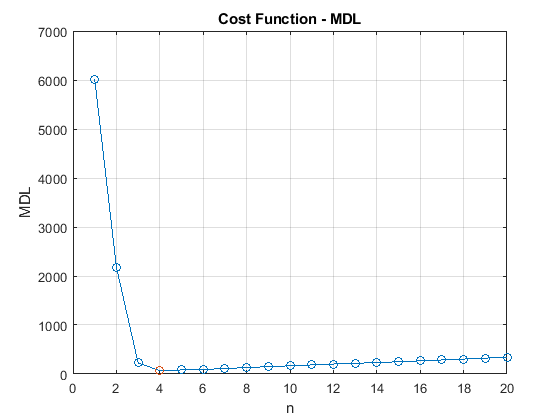

figure();
plot(MDL,'-o');
hold on;
grid on;
ylabel('MDL');
plot(min_MDL,MDL(min_MDL),'o');
xlabel('n');
title('Cost Function - MDL');

Third method is the ***AIC (AKAIKE INFORMATION CRITERION)***:


$$AIC=N log(J(\hat{\theta_N})) + 2p $$


Given a model class$ M(\theta )$, we can use this criterion to estiamte the best complexity p of the model, that gives the ‘best’ model class $Mp(\theta )$.  

The order giving the smallest value of the criterion function is selected.

for n=1:L
    Theta_LS = RLSII_AR(y,n);
    AIC(n)=AIC_criterion(y,Theta_LS);
end
[value,min_AIC]=min(AIC);
x = sprintf('min(AIC) is %d on the order %d.', value, min_AIC);
disp(x);

min(AIC) is -6.478376e+00 on the order 6.


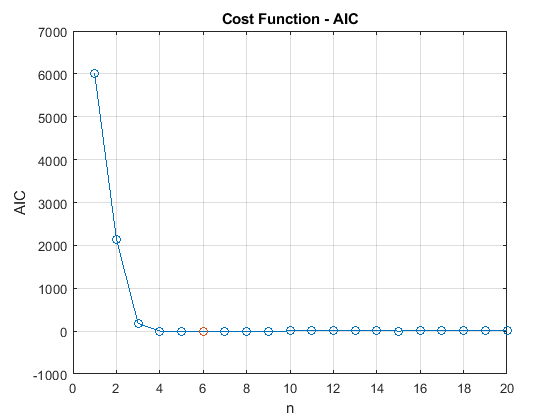

 figure();
 plot(AIC,'-o');
 hold on;
 grid on;
 ylabel('AIC');
 plot(min_AIC,AIC(min_AIC),'o');
 xlabel('n');
 title('Cost Function - AIC');

FPE and AIC do not give a consistent estimate of the model order n (the probability of overestimating the order is not null).

This is also shown in the results, because FPE and AIC returns an estimate which is greater than MDL. But even when they return the same order, the plot of the MDL shows a clearer result. 

## **4. Model validation: **

Consists in evaluating the capability of the identified model to describe the process that has generated the data in a way compatible with its planned use. 

We assume our real data well described by our model, so we can make the following assumptions about the residual  $ \epsilon(t,\hat\theta_N)$:

- $ \epsilon(t,\hat\theta_N)$ is a zero mean white process

- $ \epsilon(t,\hat\theta_N)$ is uncorrelated with the input signal $u\left(t\right)$

It is thus possible to perform the following tests on residuals:

- test of whiteness of $ \epsilon(t,\hat\theta_N)$

- test of cross-correlation between $ \epsilon(t,\hat\theta_N)$ and $u\left(t\right)$

**Whiteness test**

Computing the sequence of residuals $ \epsilon(1,\hat\theta_N),..., \epsilon(N,\hat\theta_N)$ we can use the binary statistical test:

 
$$\left\lbrace \begin{array}{l}
H_0 :\varepsilon \;\left(t\right)\;\mathrm{is}\;a\;\mathrm{zero}-\mathrm{mean}\;\mathrm{white}\;\mathrm{process}\\
H_1 :\mathrm{not}\;H_0 
\end{array}$$


We consider the sample variance $\hat{\;r_{\varepsilon } } \left(0\right)$, and the sample autocorrelations$\hat{\;r_{\varepsilon } }={\left\lbrack \begin{array}{ccc}
\hat{\;r_{\varepsilon } } \left(1\right) & \cdots  & \hat{\;r_{\varepsilon } } \left(m\right)
\end{array}\right\rbrack }^T$.

If $H_0$ is true, it asymptotically holds that 

$\hat{\;r_{\varepsilon } } \left(0\right)\to \sigma_e^2$  ,  $\hat{\;r_{\varepsilon } } \left(\tau \;\right)\to 0, \ \ 
 \ \ \forall \tau \;\not= \;0$

It is possible to prove that: $\left\lbrace \begin{array}{l}
\sqrt{N}\hat{\;r_{\varepsilon } } \to \sim N\left(0,P\right)\\
P={\mathrm{lim}}_{N\to \infty \;} E\left\lbrack N\hat{\;r_{\varepsilon } } {\hat{\;r_{\varepsilon } } }^T \right\rbrack =\sigma_e^4 I
\end{array}$	  (1)		

As a consequence, x aymptotically tends to chi-square distribution:


$$x=N\;\frac{{\hat{\;r_{\varepsilon } } }^T \hat{\;r_{\varepsilon } } }{{\hat{\;r_{\varepsilon } } }^2 \left(0\right)}\to \sim \chi {\;}^2 \left(m\right)$$


This leads to the statistical test: $\left\lbrace \begin{array}{l}
H_0 :\;x\le \chi_{\alpha }^2 \left(m\right)\;\to \;\varepsilon \;\left(t\right)\;\mathrm{is}\;a\;\mathrm{zero}-\mathrm{mean}\;\mathrm{white}\;\mathrm{process}\\
H_1 :x>\chi_{\alpha }^2 \left(m\right)\;\;\to \;\;\mathrm{not}\;\mathrm{H_0}
\end{array}$

where we choose  $\alpha$, the significance level, to perform our test. 

optimal_order=min_MDL;
Theta=RLSII_AR(y,optimal_order);
disp([Theta]);

    1.6704
    1.2968
    0.6342
    0.1315



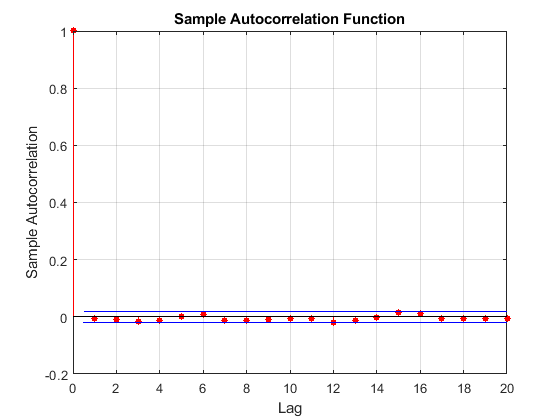

epsilon=Residual(y,Theta);%Residual
figure()
autocorr(epsilon) %Autocorrelation of epsilon

alpha=0.05; %We choose alpha 5% 
m=N/4;
[Whiteness_test]=Chi_square_whiteness(epsilon,alpha,m)

Whiteness_test = 'accepted'

We can also perform the test in a different way.

Define the normalized quantities ${\hat{\gamma}(\tau)}=\frac{{\hat{\;r_{\varepsilon } }(\tau) } }{{\hat{\;r_{\varepsilon } } }\left(0\right)}, \tau = 1,2,....m$, from (1) it follows that, asymptotically:  

$\[
\sqrt{N} \hat{\gamma}(\tau) \to{} \mathcal{N}(0,1), \quad \tau = 1, 2, \ldots, m
\]$, so that a set of m gaussian tests can be performed.

To make the final decision about the whiteness test we can use the Anderson test:


$$\left\lbrace \begin{array}{l}
H_0 :\frac{\bar \mathrm{m}}{\mathrm{m}}\le \alpha \;\;\to \;\varepsilon \;\left(t\right)\;\mathrm{is}\;a\;\mathrm{zero}-\mathrm{mean}\;\mathrm{white}\;\mathrm{process}\;\\
H_1 :\frac{\bar \mathrm{m}}{\mathrm{m}}>\alpha \;\;\to \;\mathrm{not}\;\mathrm{H_0}\;
\end{array}$$


Where (m hat) is the number of failed tests.

[Anderson_test,m_bar,m]=Anderson_whiteness(epsilon,alpha)

Anderson_test = 'accepted'

m_bar = 1

m = 20

#### **Cross-correlation tests**

This test would check that the residuals $\varepsilon$, and the input signal $u$ are uncorrelated


$$r_{\varepsilon u} \left(\tau \;\right)=0$$


It follows the test:


$$\left\lbrace \begin{array}{l}
H_0 :\varepsilon \;\left(t\right)\;\mathrm{and}\;u\left(t\right)\;\mathrm{are}\;\mathrm{uncorrelated}\\
H_1 :\mathrm{not}\;H_0 
\end{array}$$


Let's consider the following vector of sample cross-correlations:


$$\hat{\;r_{\varepsilon u} } =\frac{1}{N}\;\Sigma \;\left\lbrack \begin{array}{c}
u\left(t-\bar{\;\tau \;} -1\right)\\
\vdots \\
u\left(t-\bar{\;\tau \;} -m\right)
\end{array}\right\rbrack \varepsilon \left(t\right)=\;\left\lbrack \begin{array}{c}
{\hat{r} }_{\varepsilon u} \left(\bar{\;\tau \;} +1\right)\\
\vdots \\
{\hat{r} }_{\varepsilon u} \left(\bar{\;\tau \;} +m\right)
\end{array}\right\rbrack$$


In this case, all the terms of the cross-correlation are equal to zero, because $u\left(t\right)=0\;\forall \;t\in \Re$  so the test is not significant.

There is no $\bar{\tau \;}$ that could make our test significant.

**Covariance matrix**

Finally, the covariance matrix, as well, is a good way to evaluate the goodness of our estimation. 

The smaller the covariance, the better the estimation:


$$cov(\hat{\theta})=\frac{\hat{\sigma}_w^2 \Sigma_{\varphi}^{-1}}{N} = \hat{\sigma}_w^2 \left( H^T H \right)^{-1}
\end{equation}$$


 [C]=Covariance_matrix(Theta,y,min_MDL)

Htot = 	1.0e+04 *

    8.0325   -7.0630    5.1792   -3.6581
   -7.0630    8.0325   -7.0628    5.1792
    5.1792   -7.0628    8.0324   -7.0628
   -3.6581    5.1792   -7.0628    8.0324


J = 0.9995

C = 	1.0e+-3 *

    0.0983    0.1588    0.1128    0.0416
    0.1588    0.3374    0.2934    0.1128
    0.1128    0.2934    0.3374    0.1588
    0.0416    0.1128    0.1588    0.0983


C = 	1.0e+-3 *

    0.0983    0.1588    0.1128    0.0416
    0.1588    0.3374    0.2934    0.1128
    0.1128    0.2934    0.3374    0.1588
    0.0416    0.1128    0.1588    0.0983


## Exercise 2: Classification

In this exercise it's asked to create a classificator from a training set and test it on a new test set.

- **Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

- **Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. 

- **Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results together with the classification error on the test set.

Remember to add a brief description of the matlab function you implemented accordingly.

**P.S.: **Remember that $\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T}$ in the case of complex curves.

**P.S.: **Remember that in the case of features representing **more than two classes** you can train a classifier that divides one class with respect to all the others and you can compute one per each class against all the others. In this context, the final prediction is the maximum value obtianed by applying each of the one-vs-the-rest classifiers to a new set of features. **If this is the case, do not plot every single 1vs1 boundary and prediction, just create the final plot with all the boundaries and the relative classes.**

N=3000; %set it at a suitable amount 
 Student = 'Sharon Patrone';
 % Used by the course-provided functions to generate the personalized dataset.
 % The original matriculation number has been removed for privacy.
 Matriculation = 'YOUR_ID'; 
 [FeatureSet] = ClassifyThose(N,Student,Matriculation);
 
 Utrain  = FeatureSet.Utrain;
 Ytrain  = FeatureSet.Ytrain;
 Utest   = FeatureSet.Utest;
 Ytest   = FeatureSet.Ytest;				

**Classification**

Classification consists in assigning an input $u\left(t\right)\in \;U$ to one of the M classes (categories) $C_1 ,C_2 ,\ldotp \ldotp \ldotp ,C_M$. A possible way to represent class labels numerically is $y\left(t\right)=y^i \;\;\;\;\mathrm{if}\;u\left(t\right)\in C_i \;,\mathrm{where}\;y^i \;\mathrm{is}\;$a Mx1 vector whose elements are zero except the i-th one (equal to 1). So, the input space U is divided into M regions ,whose boundaries are called *decision boundaries*.

**1) Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

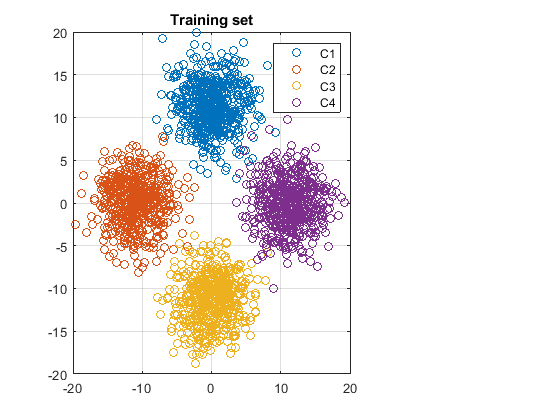

%Plot of the data
 figure();    
 subplot(1,3,[1 2]);
 plot(Utrain(find(Ytrain>0.5),1),Utrain(find(Ytrain>0.5),2),'o');
 hold on 
 grid on 
 plot(Utrain(find(Ytrain>1.5),1),Utrain(find(Ytrain>1.5),2),'o');
 hold on 
 grid on 
 plot(Utrain(find(Ytrain>2.5),1),Utrain(find(Ytrain>2.5),2),'o');
 hold on 
 grid on 
 plot(Utrain(find(Ytrain>3.5),1),Utrain(find(Ytrain>3.5),2),'o');
 title('Training set')
 legend('C1','C2','C3', 'C4')

From the plot, it can be deduced that the data can be divided into four classes by linear boundaries.

**2) Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. 


 Ntrain = round(0.7*N); %Dividing the data set in Training set and Test set.
 Ntest = N-Ntrain;
 Theta1=[0;0;0]; %Initialize the four theta vectors for the four linear boundaries.
 Theta2=[0;0;0];
 Theta3=[0;0;0];
 Theta4=[0;0;0];


%Phi_train
PHItrain = [ones(Ntrain, 1), Utrain];
Ytrain_1=Onevsall(Ntrain,Ytrain,1) 

Ytrain_1 =      0
     0
     0
     1
     1
     0
     1
     0
     0
     0


In this case, we are considering *One-vs-all* multiclass problem, so it is split into M two-class problems. The generic i–th binary problem involves the classes Ci and

$\bar{C_i }$ = {C1, . . . , Ci−1, Ci+1, . . . , CM }. 

In our case the multiclass problem is split in four two-class problems.

J = ClassCostFunc(PHItrain,Theta1,Ytrain_1) %Cost Function 1

J = -1.4556e+03

We use logistic regression: 

Consider a two-class classification problem with r inputs and assume a linear decision boundary. This boundary is an hyperplane in $\it{R^r}$ described by the equation.

$\beta_{0}+\beta_{1} u_{1}(t)+\beta_{2} u_{2}(t)+\cdots+\beta_{r} u_{r}(t)=0$. 

that is:

$\varphi^{T}(t) \theta=0$ with $\varphi(t)=\left[1 \quad u_{1}(t) \quad u_{2}(t) \quad \cdots \quad u_{r}(t)\right]^{T}
$ and $\theta=\left[\beta_{0} \quad \beta_{1} \quad \cdots \quad \beta_{r}\right]^{T}$ 

we need a function f(z(t)) where $z(t) = \varphi^{T}(t) \theta$ , such that:

– f(z) takes values in the range (0, 1) 

– f(0) = 0.5

 – f(z) > 0.5 (f(z) < 0.5) when z > 0 (z < 0) 

– f(z) → 1 when z → ∞ 

– f(z) → 0 when z → −∞

so we use the logistic sigmoid function: $f(z)=\frac{e^{z}}{1+e^{z}}=\frac{1}{1+e^{-z}}$   with     $z(t)=\varphi^{T}(t) \theta$.

Then, we use the Newton-Raphson algorithm to update theta.

Find the estimate $\hat{\vartheta}$ that maximizes the poster probability of the observation Y. So we want to know the maximum likelihood estimation. $\log P(Y \mid \theta)=\sum_{t=1}^{N}[y(t) \log f(z(t))+(1-y(t)) \log (1-f(z(t)))]$.

Maximize the above function is equivalent to minimize its negative, so we have to find the estimate$\hat{\vartheta}$ minimizing$J(\theta)= -\log P(Y \mid \theta)$

Optimization problem with Newton-Raphson algorithm:  $\hat \theta^{k+1}=\hat \theta^{k}-\eta^k J\sp{\prime \prime}(\hat \theta^{k})J'(\hat \theta^{k})^T$

With the first and second derivative with respect to theta:$J\sp{\prime }( \theta)=  \frac{\partial J( \theta)}{\partial \theta} =\sum_{t=1}^{N}[f(z(t))-y(t)]\varphi(t)=\phi^T(F(\theta)-Y)$$J\sp{\prime \prime }( \theta)=  \frac{\partial ^2J( \theta)}{\partial^2 \theta} =\sum_{t=1}^{N}f(z(t))(1-f(z(t)))\varphi(t) \varphi^T(t)=\phi^TW\phi$

$W (\theta)$ is the diagonal matrix:$W(\theta)=diag[f(z(1))(1-f(z(1))) \ f(z(2))(1-f(z(2))) \ f(z(N))(1-f(z(N)))]$

The iterative algorithm is: $\hat \theta^{k+1}=\hat \theta^{k}-\eta^k (\phi^TW\phi ) \phi^T (F(\theta)-Y)$

Let's calculate and plot the cost function of the four one-vs-all classifications.

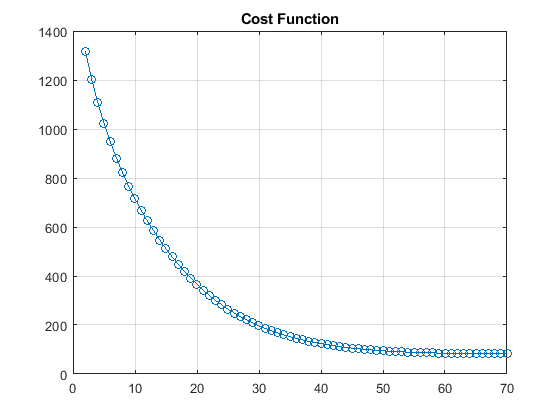

Alpha=0.1;
 k=2;
 J(1)=1000;
 
figure();
while 1
    
      grad1_J=Grad1ClassCost_func(PHItrain,Ytrain_1,Theta1);
      Grad2_J=Grad2ClassCost_func(PHItrain,Theta1);
      Theta1=Theta1-Alpha*pinv(Grad2_J)*grad1_J;
      J(k)=-ClassCostFunc(PHItrain,Theta1,Ytrain_1);    
      
      if (abs(J(k)-J(k-1))<0.1) 
         break;
      end

    plot(2:k,J(2:k),'o-');
    grid on;
    title('Cost Function')

     pause(0.1);
     k=k+1;

end

 Ytrain_2=Onevsall(Ntrain,Ytrain,2)

Ytrain_2 =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


 J = ClassCostFunc(PHItrain,Theta2,Ytrain_2)

J = -1.4556e+03

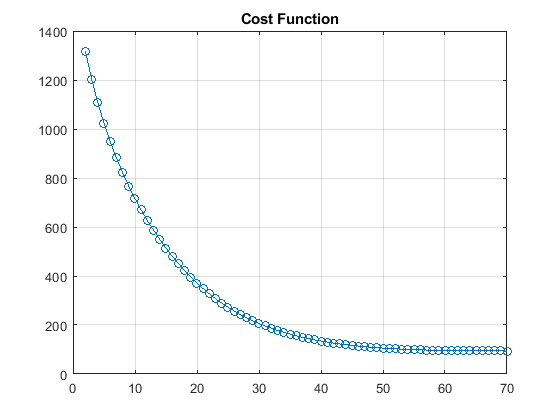

Alpha=0.1;
 k=2;
 J(1)=1000;
 
figure();
while 1
    
      grad1_J=Grad1ClassCost_func(PHItrain,Ytrain_2,Theta2);
      Grad2_J=Grad2ClassCost_func(PHItrain,Theta2);
      Theta2=Theta2-Alpha*pinv(Grad2_J)*grad1_J;
      J(k)=-ClassCostFunc(PHItrain,Theta2,Ytrain_2);    
     
      if (abs(J(k)-J(k-1))<0.1) 
         break;
      end


    plot(2:k,J(2:k),'o-');
    grid on;
    title('Cost Function')

     pause(0.1);
     k=k+1;
end

Ytrain_3=Onevsall(Ntrain,Ytrain,3)

Ytrain_3 =      0
     0
     1
     0
     0
     0
     0
     0
     1
     1


J = ClassCostFunc(PHItrain,Theta3,Ytrain_3)

J = -1.4556e+03

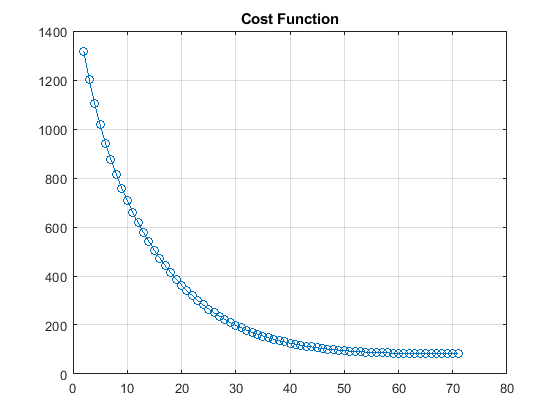

Alpha=0.1;
 k=2;
 J(1)=1000;
 
figure();
while 1
    
      grad1_J=Grad1ClassCost_func(PHItrain,Ytrain_3,Theta3);
      Grad2_J=Grad2ClassCost_func(PHItrain,Theta3);
      Theta3=Theta3-Alpha*pinv(Grad2_J)*grad1_J;
      J(k)=-ClassCostFunc(PHItrain,Theta3,Ytrain_3);    
     
      if (abs(J(k)-J(k-1))<0.1) 
         break;
      end

    plot(2:k,J(2:k),'o-');
    grid on;
    title('Cost Function')

   
     pause(0.1);
     k=k+1;
end

Ytrain_4=Onevsall(Ntrain,Ytrain,4)

Ytrain_4 =      1
     1
     0
     0
     0
     1
     0
     0
     0
     0


J = ClassCostFunc(PHItrain,Theta4,Ytrain_4)

J = -1.4556e+03

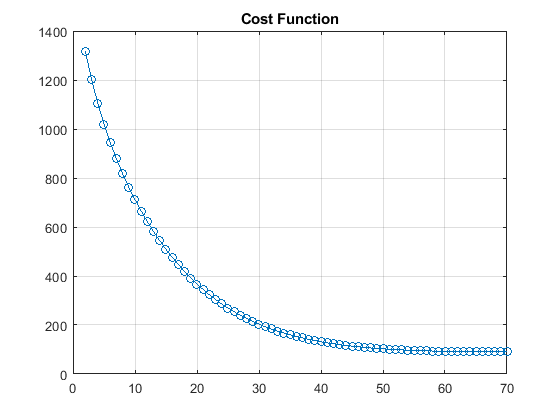

Alpha=0.1;
 k=2;
 J(1)=1000;
 
figure();
while 1
    
      grad1_J=Grad1ClassCost_func(PHItrain,Ytrain_4,Theta4);
      Grad2_J=Grad2ClassCost_func(PHItrain,Theta4);
      Theta4=Theta4-Alpha*pinv(Grad2_J)*grad1_J;
      J(k)=-ClassCostFunc(PHItrain,Theta4,Ytrain_4);    
     
      if (abs(J(k)-J(k-1))<0.1) 
         break;
      end

    plot(2:k,J(2:k),'o-');
    grid on;
    title('Cost Function')

   
     pause(0.1);
     k=k+1;
end

Finally, we can plot the four decision boundaries.

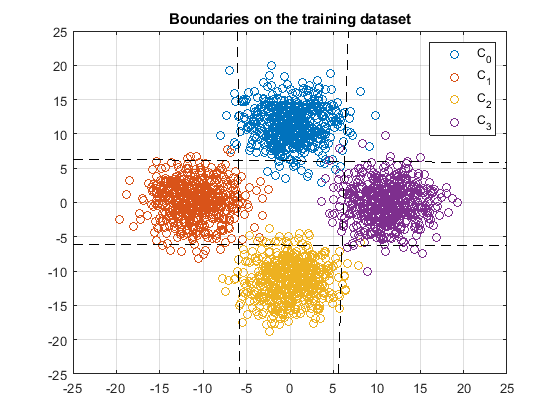

 figure();
 plot(Utrain(find(Ytrain>0.5),1),Utrain(find(Ytrain>0.5),2),'o');
 hold on 
 grid on 
 plot(Utrain(find(Ytrain>1.5),1),Utrain(find(Ytrain>1.5),2),'o');
 hold on 
 grid on 
 plot(Utrain(find(Ytrain>2.5),1),Utrain(find(Ytrain>2.5),2),'o');
 hold on 
 grid on 
 plot(Utrain(find(Ytrain>3.5),1),Utrain(find(Ytrain>3.5),2),'o');

xspace = -30:0.1:30;
BoundaryLine = (Theta1(1) + xspace.*Theta1(2))./(-Theta1(3));
plot(xspace,BoundaryLine,'--k');

xspace = -30:0.1:30;
BoundaryLine = (Theta2(1) + xspace.*Theta2(2))./(-Theta2(3));
plot(xspace,BoundaryLine,'--k');

xspace = -30:0.1:30;
BoundaryLine = (Theta3(1) + xspace.*Theta3(2))./(-Theta3(3));
plot(xspace,BoundaryLine,'--k');

xspace = -30:0.1:30;
BoundaryLine = (Theta4(1) + xspace.*Theta4(2))./(-Theta4(3));
plot(xspace,BoundaryLine,'--k');

title('Boundaries on the training dataset');
legend({'C_0','C_1','C_2', 'C_3'});
xlim([-25 25])
ylim([-25 25])

**3) Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results together with the classification error on the test set.

In order to verify my classifier, we can use the error rate for each class. 

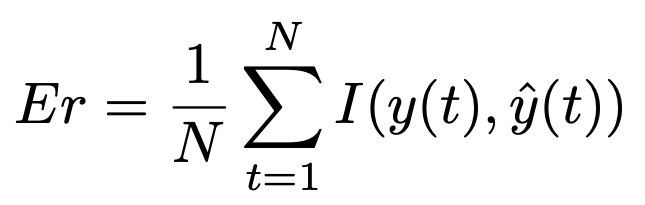

So we can use the sigmoid:

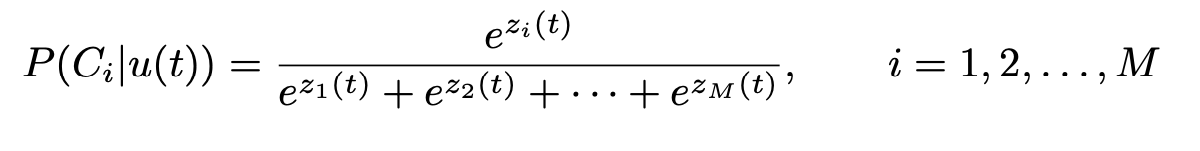

Yhat1 = Sigmoid_Multiclass(PHItrain*Theta1,PHItrain*Theta2,PHItrain*Theta3,PHItrain*Theta4);
Yhat1 = double(Yhat1>0.5);
Classification_Error_Class1_TrainingSet = 1/(Ntrain)*((abs(Yhat1-Ytrain_1))'*(abs(Yhat1-Ytrain_1)))

Classification_Error_Class1_TrainingSet = 0.0043

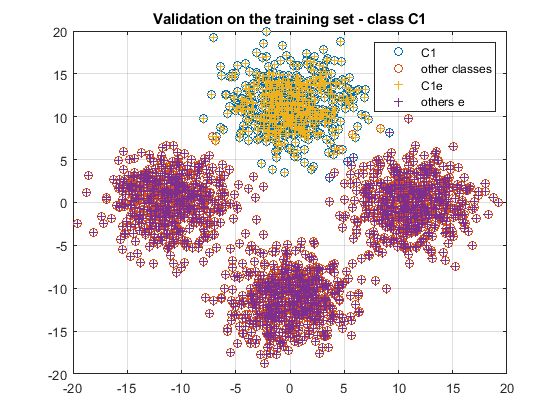

%plot
figure();
    plot(Utrain(find(Ytrain_1>0.5),1),Utrain(find(Ytrain_1>0.5),2),'o');
    hold on 
    grid on 
    plot(Utrain(find(Ytrain_1<0.5),1),Utrain(find(Ytrain_1<0.5),2),'o');
    plot(Utrain(find(Yhat1>0.5),1),Utrain(find(Yhat1>0.5),2),'+');
    plot(Utrain(find(Yhat1<0.5),1),Utrain(find(Yhat1<0.5),2),'+');

    Title = sprintf('Validation on the training set - class C1');
    title(Title);
    legend({'C1 ','other classes','C1e','others e'});
    
xlim('auto')
ylim('auto')

Now we can also test all the other results:

Yhat2 = Sigmoid_Multiclass(PHItrain*Theta2,PHItrain*Theta1,PHItrain*Theta3,PHItrain*Theta4);
Yhat2 = double(Yhat2>0.5);
Classification_Error_Class2_TrainingSet = 1/(Ntrain)*((abs(Yhat2-Ytrain_2))'*(abs(Yhat2-Ytrain_2)))

Classification_Error_Class2_TrainingSet = 0.0019

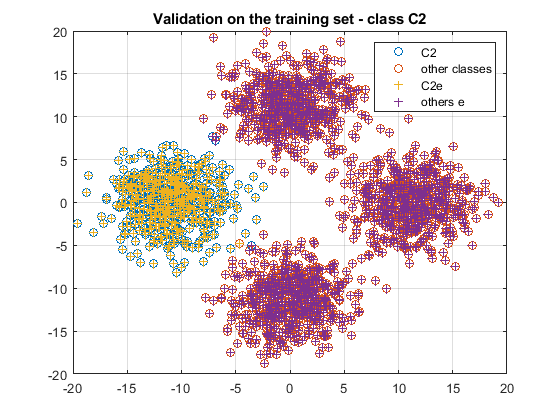

%plot
figure();
    plot(Utrain(find(Ytrain_2>0.5),1),Utrain(find(Ytrain_2>0.5),2),'o');
    hold on 
    grid on 
    plot(Utrain(find(Ytrain_2<0.5),1),Utrain(find(Ytrain_2<0.5),2),'o');
    plot(Utrain(find(Yhat2>0.5),1),Utrain(find(Yhat2>0.5),2),'+');
    plot(Utrain(find(Yhat2<0.5),1),Utrain(find(Yhat2<0.5),2),'+');

    Title = sprintf('Validation on the training set - class C2');
    title(Title);
    legend({'C2 ','other classes','C2e','others e'});
    
xlim('auto')
ylim('auto')

Yhat3 = Sigmoid_Multiclass(PHItrain*Theta3,PHItrain*Theta1,PHItrain*Theta2,PHItrain*Theta4);
Yhat3 = double(Yhat3>0.5);
Classification_Error_Class3_TrainingSet = 1/(Ntrain)*((abs(Yhat3-Ytrain_3))'*(abs(Yhat3-Ytrain_3)))

Classification_Error_Class3_TrainingSet = 0.0019

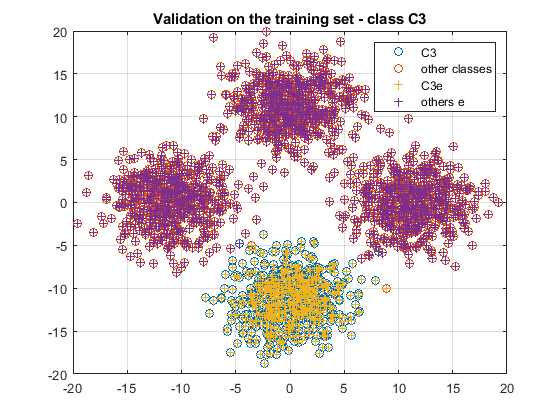

%plot
figure();
    plot(Utrain(find(Ytrain_3>0.5),1),Utrain(find(Ytrain_3>0.5),2),'o');
    hold on 
    grid on 
    plot(Utrain(find(Ytrain_3<0.5),1),Utrain(find(Ytrain_3<0.5),2),'o');
    plot(Utrain(find(Yhat3>0.5),1),Utrain(find(Yhat3>0.5),2),'+');
    plot(Utrain(find(Yhat3<0.5),1),Utrain(find(Yhat3<0.5),2),'+');

    Title = sprintf('Validation on the training set - class C3');
    title(Title);
    legend({'C3 ','other classes','C3e','others e'});
    
xlim('auto')
ylim('auto')

Yhat4 = Sigmoid_Multiclass(PHItrain*Theta4,PHItrain*Theta1,PHItrain*Theta2,PHItrain*Theta3);
Yhat4 = double(Yhat4>0.5);
Classification_Error_Class4_TrainingSet = 1/(Ntrain)*((abs(Yhat4-Ytrain_4))'*(abs(Yhat4-Ytrain_4)))

Classification_Error_Class4_TrainingSet = 0.0043

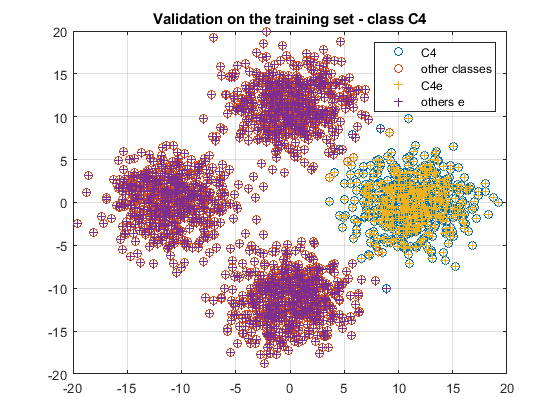

%plot
figure();
    plot(Utrain(find(Ytrain_4>0.5),1),Utrain(find(Ytrain_4>0.5),2),'o');
    hold on 
    grid on 
    plot(Utrain(find(Ytrain_4<0.5),1),Utrain(find(Ytrain_4<0.5),2),'o');
    plot(Utrain(find(Yhat4>0.5),1),Utrain(find(Yhat4>0.5),2),'+');
    plot(Utrain(find(Yhat4<0.5),1),Utrain(find(Yhat4<0.5),2),'+');

    Title = sprintf('Validation on the training set - class C4');
    title(Title);
    legend({'C4 ','other classes','C4e','others e'});
    
xlim('auto')
ylim('auto')